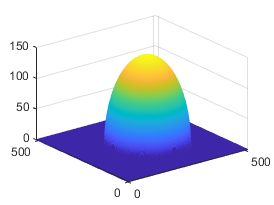

clc
clear all
clf

geometry_number=1;
dir_root='E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\test_dataset_0409';
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   测试生成的.mat文件         %%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%\

geometry=load([dir_root '\geometry\' num2str(geometry_number) '.mat'],'geometry');


geometry=geometry.geometry;
figure;
mesh(geometry);

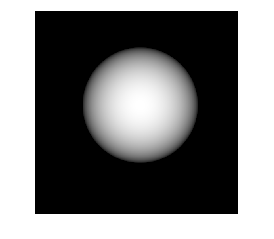

figure;
imshow(geometry,[]);

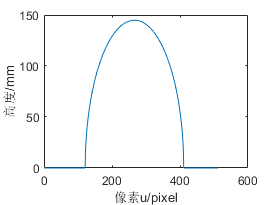

figure;
plot(geometry(256,:));xlabel('像素u/pixel');ylabel('高度/mm'); 

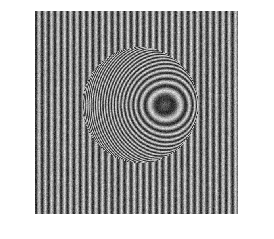

high_fre_grating=load([dir_root '\high_fre_grating\' num2str(geometry_number) '.mat'],'high_fre_grating');
%load载入.mat文件，得到的是个structure类型的数据，需要再等于另外一个变量进行赋值，才会转为矩阵形式
high_fre_grating=high_fre_grating.high_fre_grating;
figure;
imshow(high_fre_grating,[]);

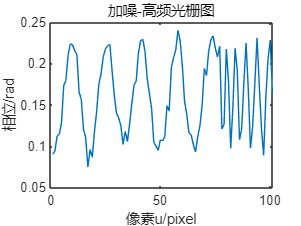

figure;
plot(high_fre_grating(200,50:150));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('加噪-高频光栅图')

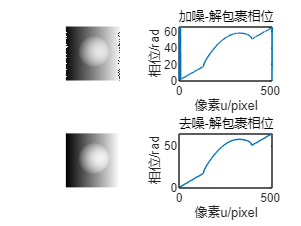


phi_unwrapped=load([dir_root '\phi_unwrapped\' num2str(geometry_number) '.mat'],'phi_unwrapped');
phi_unwrapped=phi_unwrapped.phi_unwrapped;
figure;
subplot(2,2,1);
imshow(phi_unwrapped,[]);
subplot(2,2,2);
plot(phi_unwrapped(300,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
title('加噪-解包裹相位')

phi_unwrapped_no_noisy=load([dir_root '\phi_unwrapped_no_noisy\' num2str(geometry_number) '.mat'],'phi_unwrapped');
phi_unwrapped_no_noisy=phi_unwrapped_no_noisy.phi_unwrapped;
subplot(2,2,3);
imshow(phi_unwrapped_no_noisy,[]);
subplot(2,2,4);
plot(phi_unwrapped_no_noisy(300,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
title('去噪-解包裹相位')

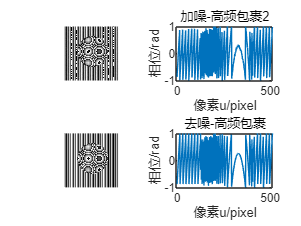



phi_wrapped_high=load([dir_root '\phi_wrapped_high\' num2str(geometry_number) '.mat'],'phi_wrapped_high');
phi_wrapped_high=phi_wrapped_high.phi_wrapped_high;
figure;
subplot(2,2,1);
imshow(phi_wrapped_high,[]);
subplot(2,2,2);
plot(phi_wrapped_high(200,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
title('加噪-高频包裹2')

phi_wrapped_high_no_noisy=load([dir_root '\phi_wrapped_high_no_noisy\' num2str(geometry_number) '.mat'],'phi_wrapped_high');
phi_wrapped_high_no_noisy=phi_wrapped_high_no_noisy.phi_wrapped_high;
subplot(2,2,3);
imshow(phi_wrapped_high_no_noisy,[]);
subplot(2,2,4);
plot(phi_wrapped_high_no_noisy(200,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
title('去噪-高频包裹')

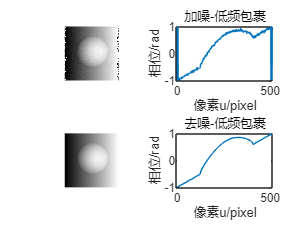



phi_wrapped_low=load([dir_root '\phi_wrapped_low\' num2str(geometry_number) '.mat'],'phi_wrapped_low');
phi_wrapped_low=phi_wrapped_low.phi_wrapped_low;
figure;
subplot(2,2,1);
imshow(phi_wrapped_low,[]);
subplot(2,2,2);
plot(phi_wrapped_low(200,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
title('加噪-低频包裹')

phi_wrapped_low_no_noisy=load([dir_root '\phi_wrapped_low_no_noisy\' num2str(geometry_number) '.mat'],'phi_wrapped_low');
phi_wrapped_low_no_noisy=phi_wrapped_low_no_noisy.phi_wrapped_low;
subplot(2,2,3);
imshow(phi_wrapped_low_no_noisy,[]);
subplot(2,2,4);
plot(phi_wrapped_low_no_noisy(200,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
title('去噪-低频包裹')

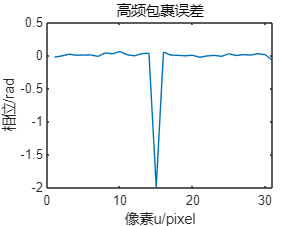




figure;
e1=phi_wrapped_high-phi_wrapped_high_no_noisy;

plot(e1(200,50:80)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
title('高频包裹误差')

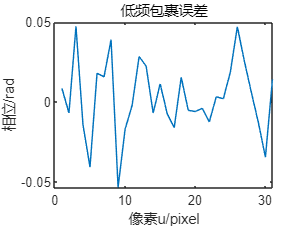



figure;
e2=phi_wrapped_low-phi_wrapped_low_no_noisy;

plot(e2(200,50:80)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
title('低频包裹误差')

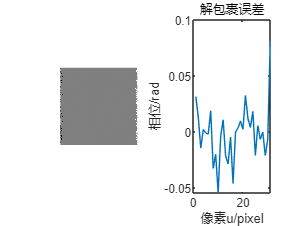



figure;
e3=phi_unwrapped_no_noisy-phi_unwrapped;
subplot(1,2,1);
imshow(e3,[]);
subplot(1,2,2);
plot(e3(200,50:80)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
title('解包裹误差')


disp('运行结束')

运行结束
